Labo A - Principes van digitale signaalverwerking

2.4 Datasets:

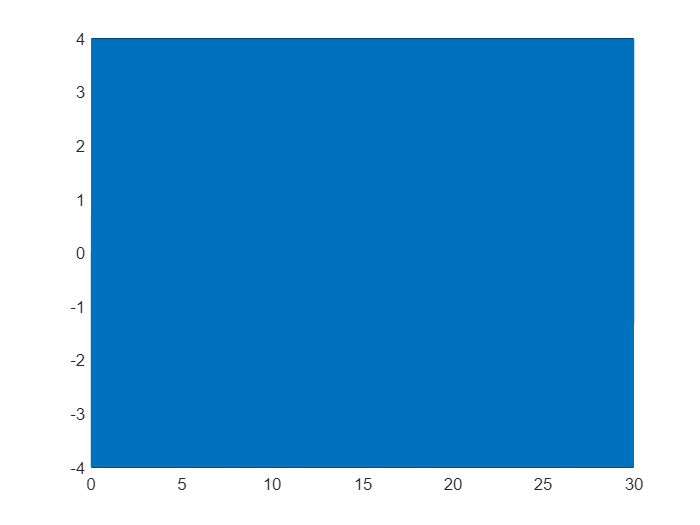

r = 4;
f = 440;
fs = 8192;
Ts = 1/fs;
t = (0:Ts:30);

a = r * sin(2 * pi * f * t);
plot(t, a)

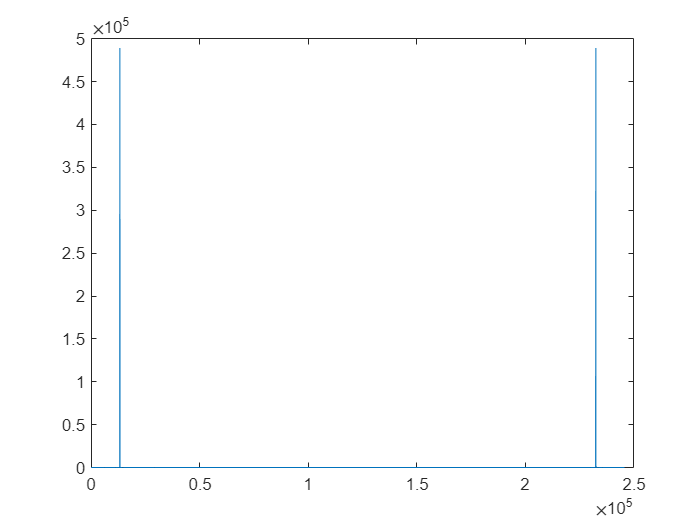

plot(abs(fft(a)))

b = load('handel')

b = struct with fields:
     y: [73113×1 double]
    Fs: 8192


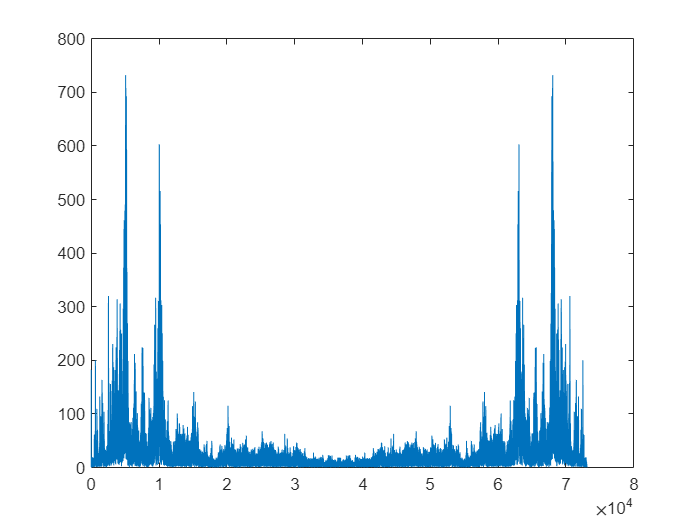

plot(abs(fft(b.y)))

c = readtable("covid19(1).csv")

c = 968×2 table
       Var1       Var2
    __________    ____

    7.3785e+05     19 
    7.3785e+05     19 
    7.3785e+05     34 
    7.3785e+05     53 
    7.3786e+05     81 
    7.3786e+05    110 
    7.3786e+05     27 
    7.3786e+05     64 
    7.3786e+05     94 
    7.3786e+05     99 
    7.3786e+05    174 
    7.3786e+05    250 
    7.3786e+05    338 
    7.3786e+05    179 
    7.3786e+05    214 
    7.3787e+05    387 


c = c.Var2

c =     19
    19
    34
    53
    81
   110
    27
    64
    94
    99


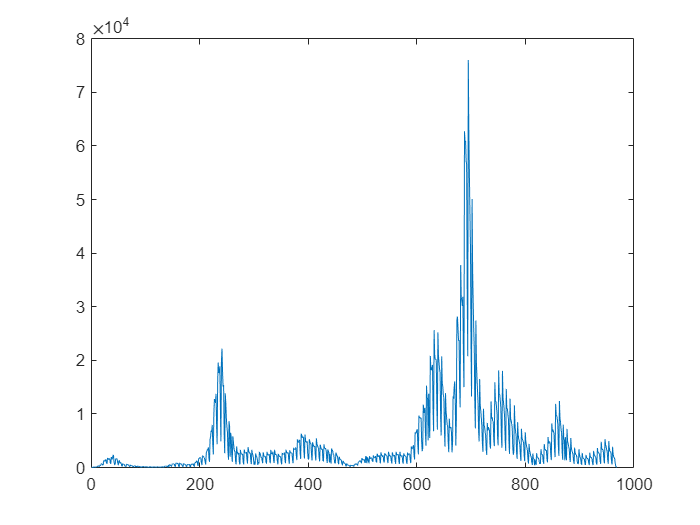

plot(c)

Sampling:

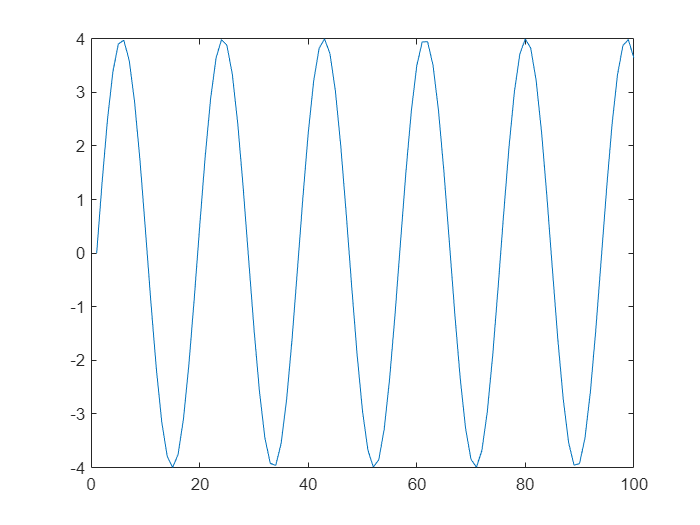

plot(a(1:100))

Discrete tijdsdomein eerste 100 samples:

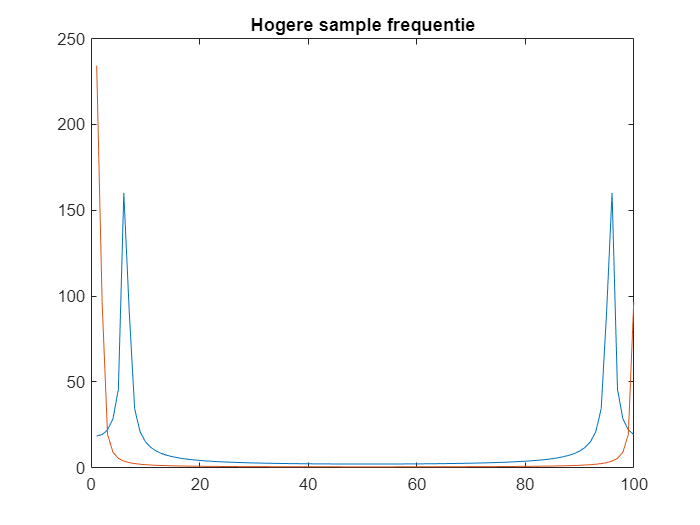

plot(abs(fft(a(1:100))))
title('Hogere sample frequentie')
hold on

fs = fs * 10;
Ts = 1/fs;
t = (0:Ts:30);
a = r * sin(2 * pi * f * t);
plot(abs(fft(a(1:100))))
hold off

We horen een zeer storend geluid...

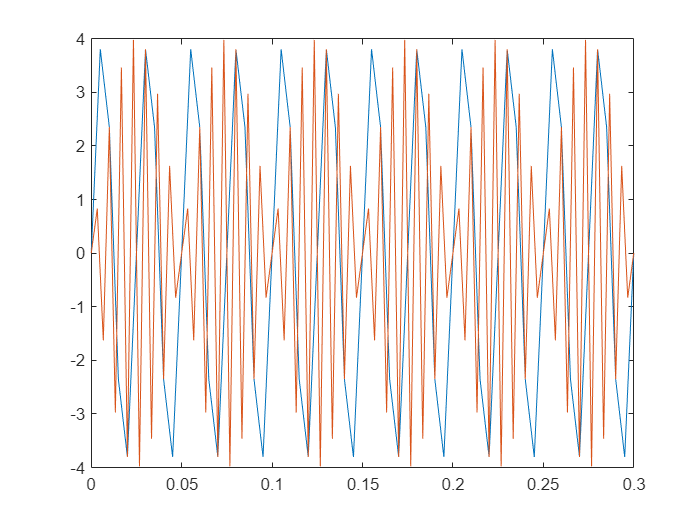

fs = 200;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

hold on

fs = 300;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

hold off

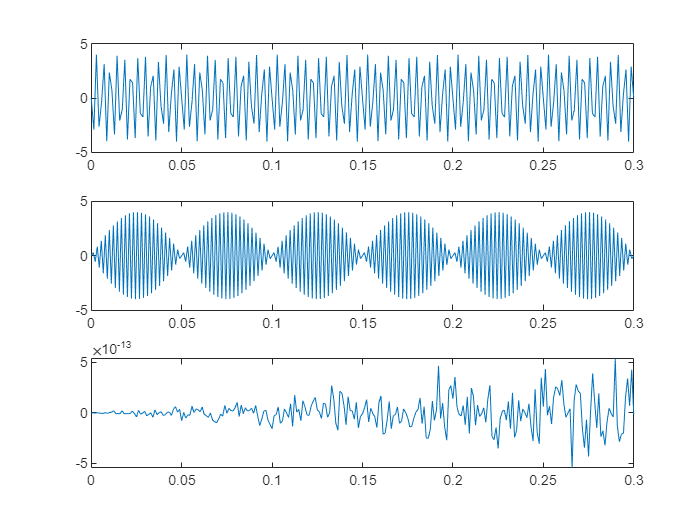

subplot(3, 1, 1);

fs = 700;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

subplot(3, 1, 2);
fs = 900;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

subplot(3, 1, 3);
fs = 880;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

Wanneer we deze samplefrequentie te laag nemen (onder de 2x de frequentie), dan is het stelsel van Nyquist niet tevreden en treed er aliasing op.

wanneer de sample frequentie exact gelijk is aan 2x de frequentie, dan krijgen we een lijn die (praktisch) nul is. Deze toont anders aan omdat de schaal zeer klein is en dit is denk ik doordat er enkele afrondingen gebeuren

Kwantisatie:

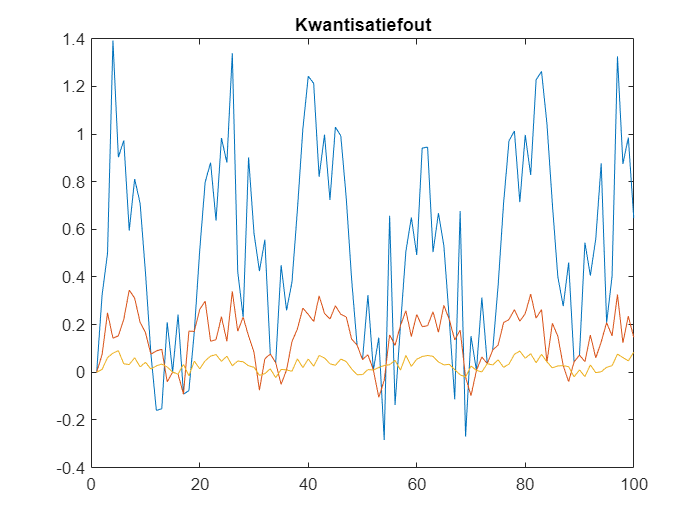

figure;

fs = 8192;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 3) - 1) * a0;
a2 = round(a1);
a3 = a2 * (max(a) - min(a)) / (power(2, 3)) + min(a);

plot(a(1:100) - a3(1:100))
hold on

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 5) - 1) * a0;
a2 = round(a1);
a5 = a2 * (max(a) - min(a)) / (power(2, 5)) + min(a);

plot(a(1:100) - a5(1:100))
hold on

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 7) - 1) * a0;
a2 = round(a1);
a7 = a2 * (max(a) - min(a)) / (power(2, 7)) + min(a);

plot(a(1:100) - a7(1:100))
title('Kwantisatiefout');
hold off

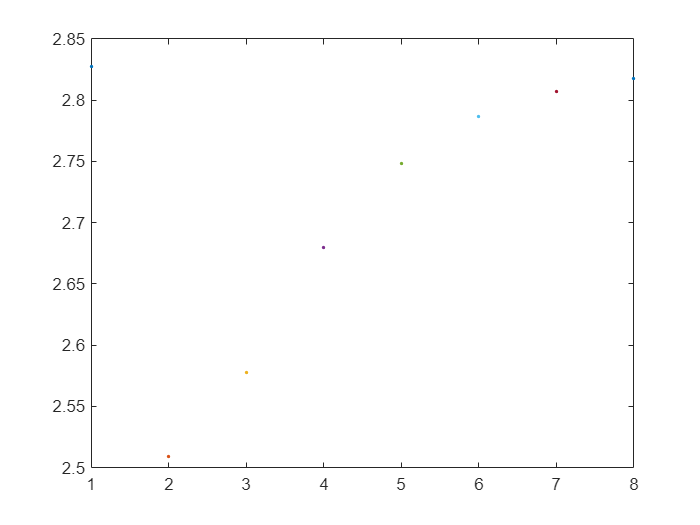

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 1) - 1) * a0;
a2 = round(a1);
b1 = a2 * (max(a) - min(a)) / (power(2, 1)) + min(a);

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 2) - 1) * a0;
a2 = round(a1);
b2 = a2 * (max(a) - min(a)) / (power(2, 2)) + min(a);

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 3) - 1) * a0;
a2 = round(a1);
b3 = a2 * (max(a) - min(a)) / (power(2, 3)) + min(a);

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 4) - 1) * a0;
a2 = round(a1);
b4 = a2 * (max(a) - min(a)) / (power(2, 4)) + min(a);

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 5) - 1) * a0;
a2 = round(a1);
b5 = a2 * (max(a) - min(a)) / (power(2, 5)) + min(a);

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 6) - 1) * a0;
a2 = round(a1);
b6 = a2 * (max(a) - min(a)) / (power(2, 6)) + min(a);

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 7) - 1) * a0;
a2 = round(a1);
b7 = a2 * (max(a) - min(a)) / (power(2, 7)) + min(a);

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 8) - 1) * a0;
a2 = round(a1);
b8 = a2 * (max(a) - min(a)) / (power(2, 8)) + min(a);
%b8 = kwantiseer(a, 8);


plot(1, rms(b1), '.')
hold on
plot(2, rms(b2), '.')
hold on
plot(3, rms(b3), '.')
hold on
plot(4, rms(b4), '.')
hold on
plot(5, rms(b5), '.')
hold on
plot(6, rms(b6), '.')
hold on
plot(7, rms(b7), '.')
hold on
plot(8, rms(b8), '.')
hold off

Dit resultaat is niet bepaald zoals verwacht, men zou denken dat de afwijking verkleint als de kwantisatie preciezer is.

2.7 Handel

b = load('handel')

b = struct with fields:
     y: [73113×1 double]
    Fs: 8192


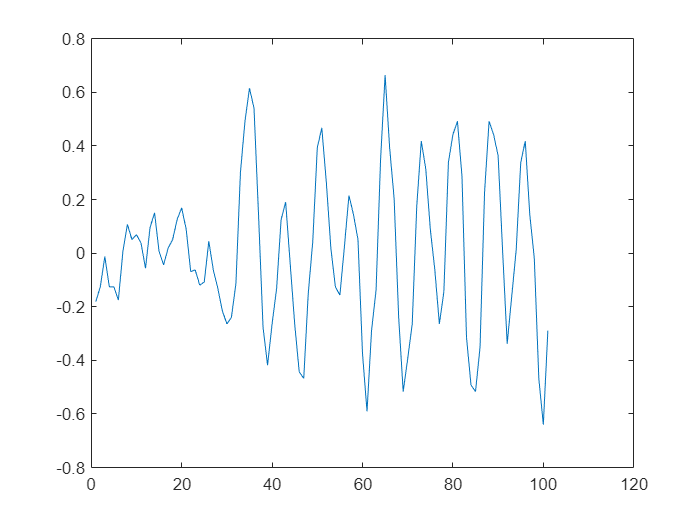

plot(b.y(4000:4100))

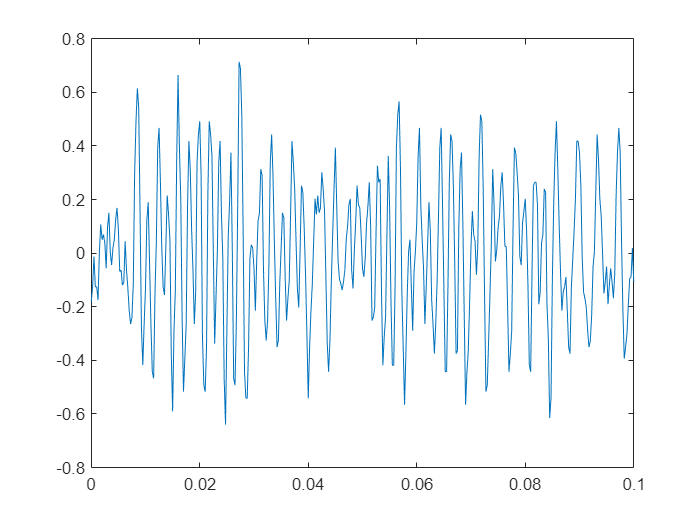

fs = 4000;
Ts = 1/fs;
t = (0:Ts:0.1);

plot(t, b.y(4000:(3999+length(t))))

Bij het afspelen op hogere sample freq gebeurt er weinig, als men dit afspeelt op lagere sample frequentie aan de andere kant, dan verandert het geluid.

Er komt dan minder detail in te zitten (en dus hogere frequenties worden minder afgespeeld).

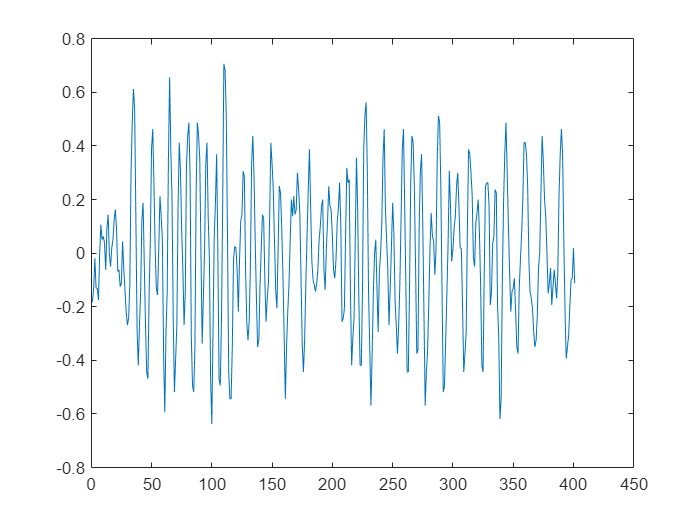

a8 = kwantiseer(b.y, 8);

plot(a8(4000:3999+length(t)))

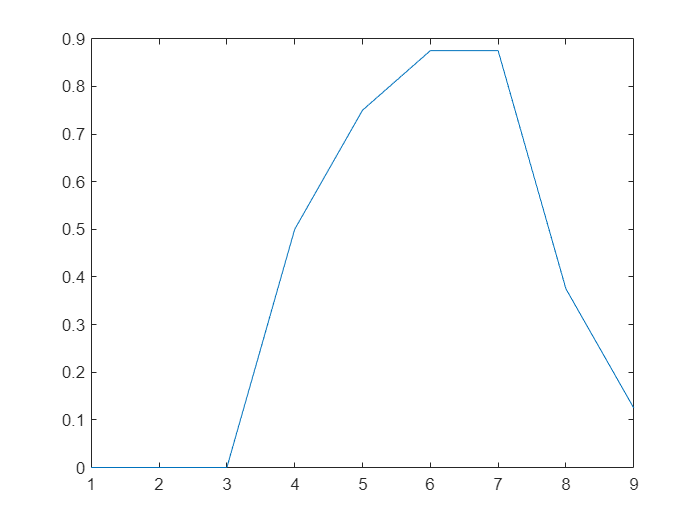

u = [0, 0, 0, 1, 1, 1, 1];
f1 = [0.5, 0.25, 0.125];
f2 = [1/3, 1/3, 1/3];
f3 = [1/9, 1/9, 1/9, 1/9, 1/9, 1/9, 1/9, 1/9, 1/9];
plot(conv(u, f1))

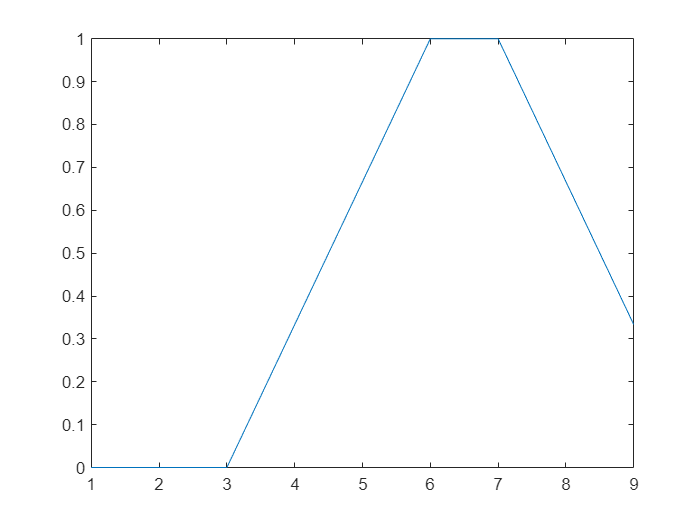

plot(conv(u, f2)) % moving average filter

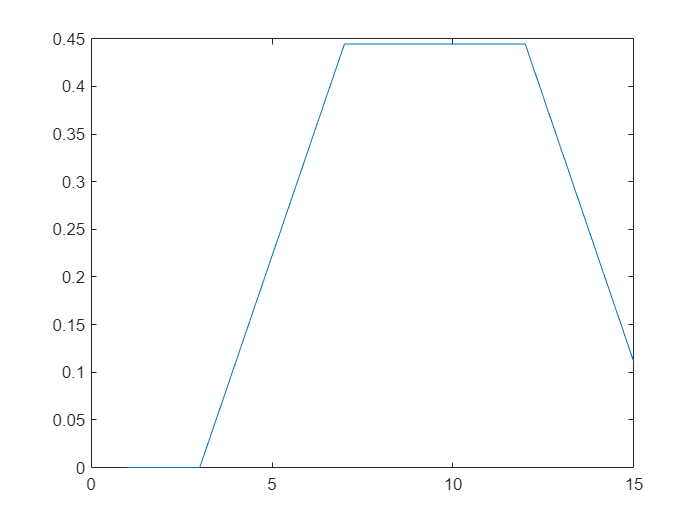

plot(conv(u, f3))

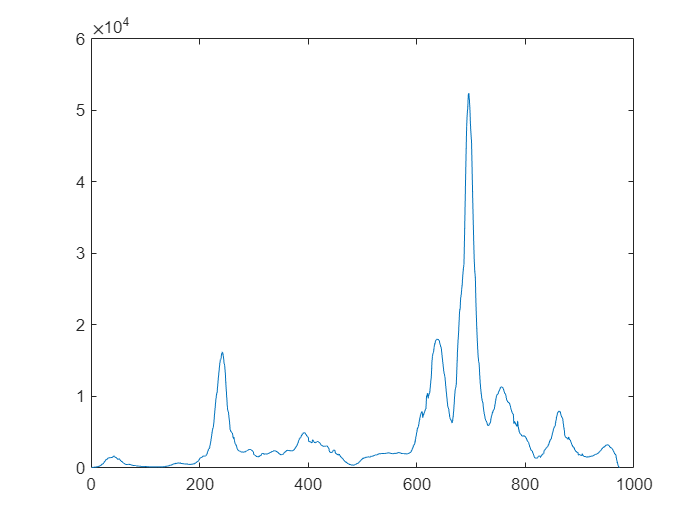

% sound(conv(b.y, f3)) minder luid, minder hoge freq
% sound(b.y)

f4 = [1, 1, 1, 1, 1, 1, 1]/7;
plot(conv(c, f4)) % laagdoorlaat

2.9 FFT

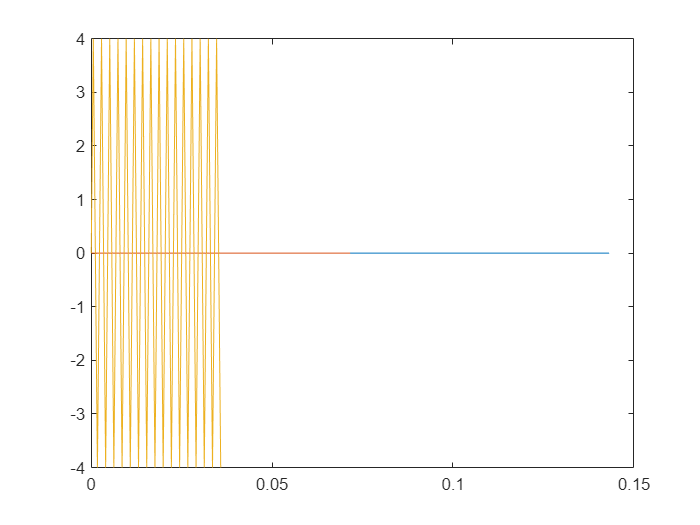

fs = f;
Ts = 1/fs;
n = 64;
t = (0:n-1) * Ts;
% t = (0:Ts:0.3);
a1 = r * sin(2 * pi * f * t);
plot(t, a1)

hold on

fs = f * 2;
Ts = 1/fs;
t = (0:n-1) * Ts;
a2 = r * sin(2 * pi * f * t);
plot(t, a2)

hold on

fs = f * 4;
Ts = 1/fs;
t = (0:n-1) * Ts;
a3 = r * sin(2 * pi * f * t);
plot(t, a3)

hold off

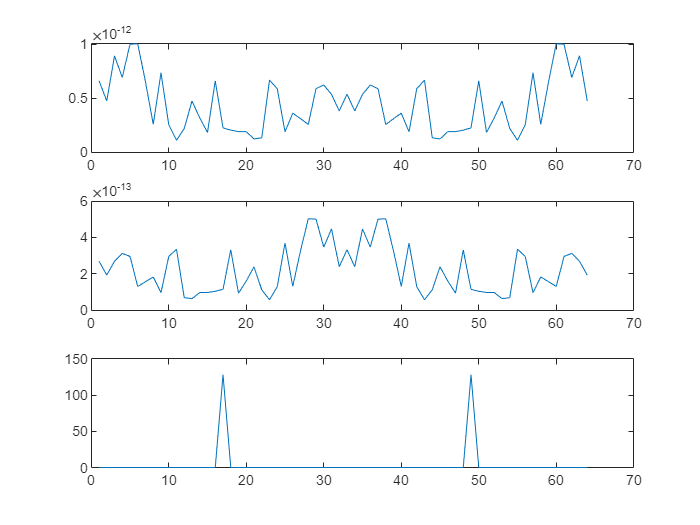

subplot(3, 1, 1);
plot(abs(fftshift(fft(a1))))
subplot(3, 1, 2);
plot(abs(fftshift(fft(a2))))
subplot(3, 1, 3);
plot(abs(fftshift(fft(a3))))

figure;

We zien dat het signaal dat 4*f gesampled is duidelijk bestaat uit 2 frequenties terwijl de andere samplefrequenties zorgen voor een onduidelijk signaal.

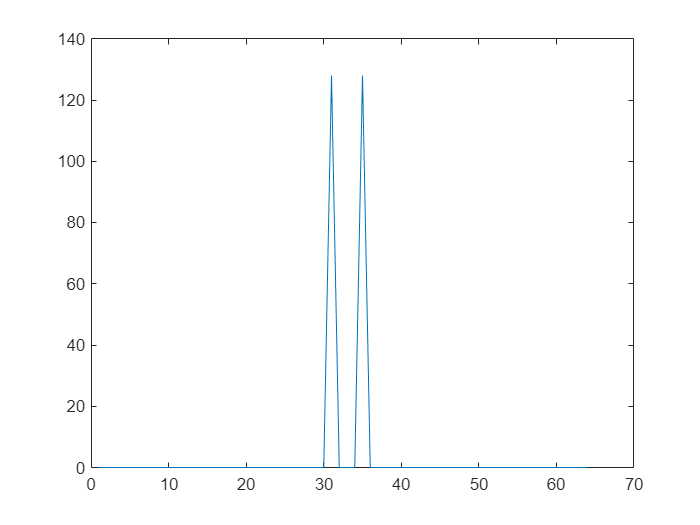

fs = f * 32;
Ts = 1/fs;
t = (0:n-1) * Ts;
a4 = r * sin(2 * pi * f * t);
plot(abs(fftshift(fft(a4))))

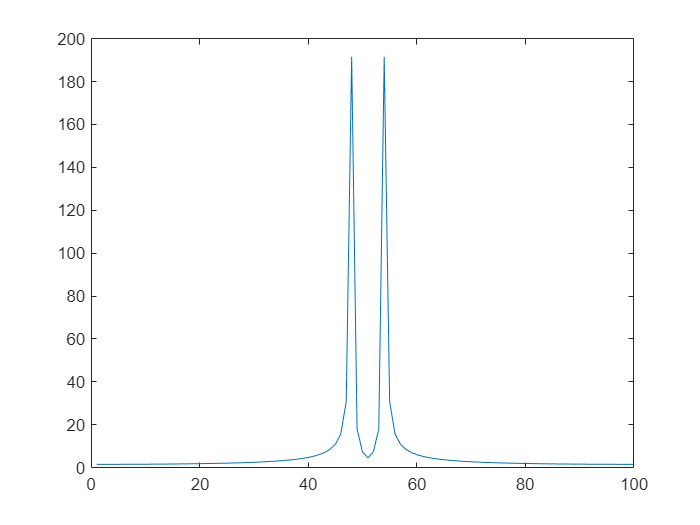

fs = f * 32;
Ts = 1/fs;
n = 100;
t = (0:n-1) * Ts;
a5 = r * sin(2 * pi * f * t);
plot(abs(fftshift(fft(a5))))

2.10 Windowing

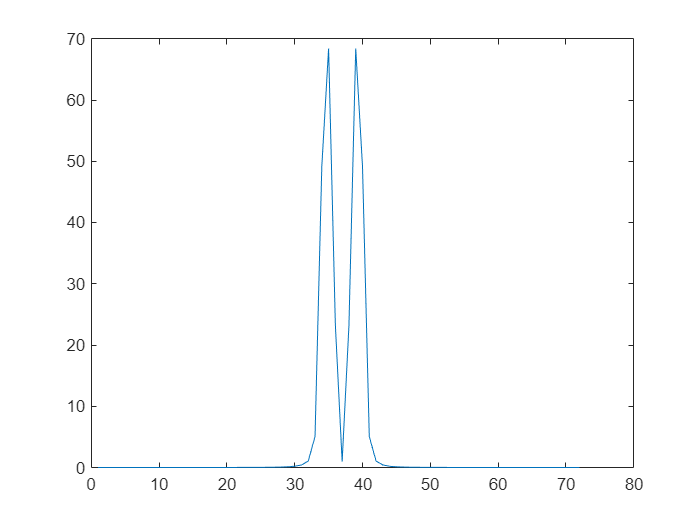

getal = (100 - 72)/2;
a6 = a5(getal + 1:end-getal);
rechthoekig = ones([72, 1])';
han = hann(72)';
ham = hamming(72)';

plot(abs(fftshift(fft(a6.*han))))

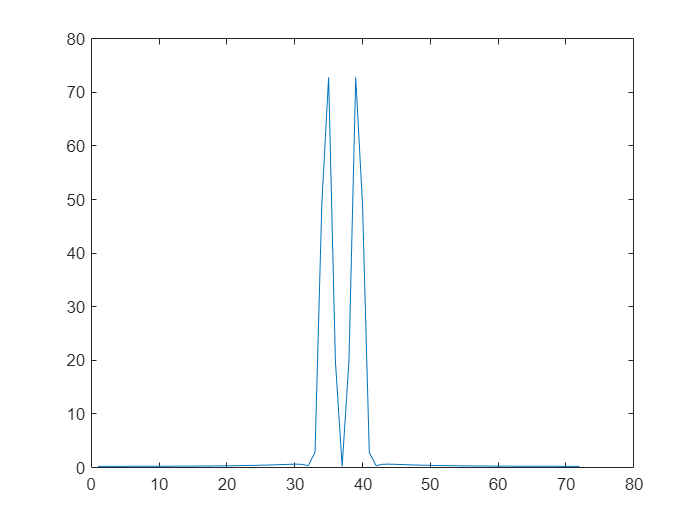

plot(abs(fftshift(fft(a6.*ham)))) % dit is mijn keuze :)

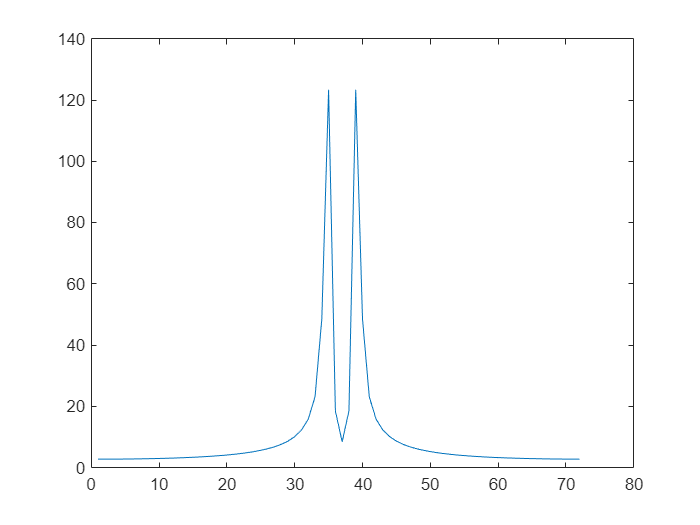

plot(abs(fftshift(fft(a6.*rechthoekig))))

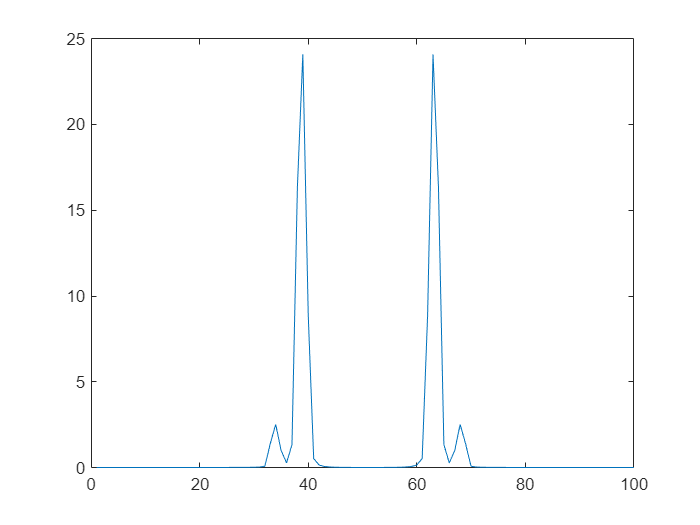

fs = 8192;
n = 100;
f1 = 1000;
delta = 400;
f2 = f1 + delta;
Ts = 1/fs;
t = (0:n-1) * Ts;
x1 = sin(2 * pi * f1 * t);
x2 = sin(2 * pi * f2 * t);
x = x1 + 0.1 * x2;

rechthoekig = ones([100, 1])';
han = hann(100)';
ham = hamming(100)';

plot(abs(fftshift(fft(x.*han))))

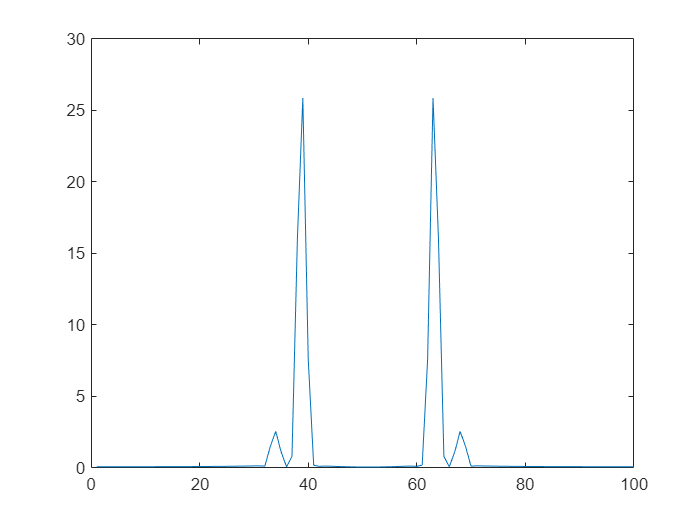

plot(abs(fftshift(fft(x.*ham))))

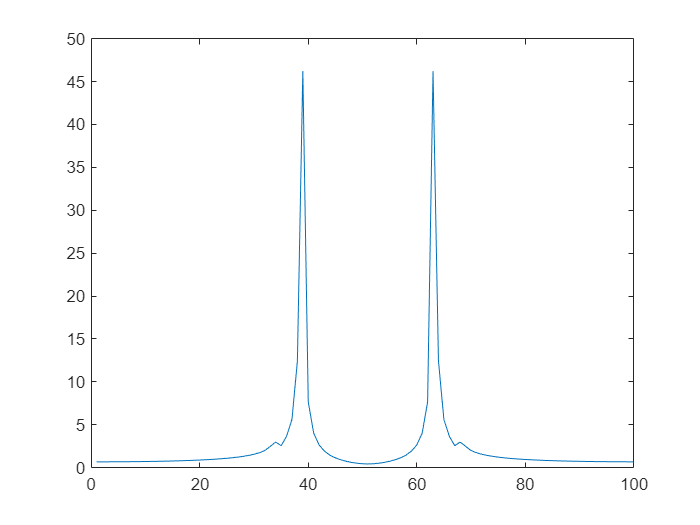

plot(abs(fftshift(fft(x.*rechthoekig))))

2.11 Ruis, windowing en interpolatie

n = rand([100, 1])';
x = x1 + 0.5 * x2 + 0.1 * n;
mean(n)

ans = 0.5249

std(n)

ans = 0.2813

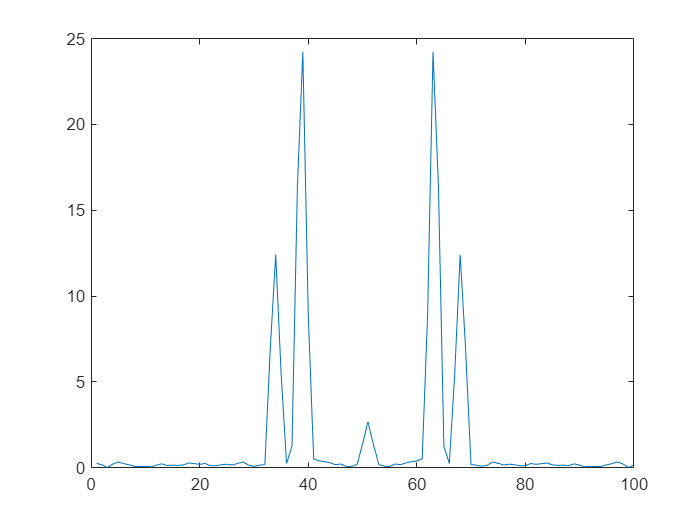

plot(abs(fftshift(fft(x.*han))))

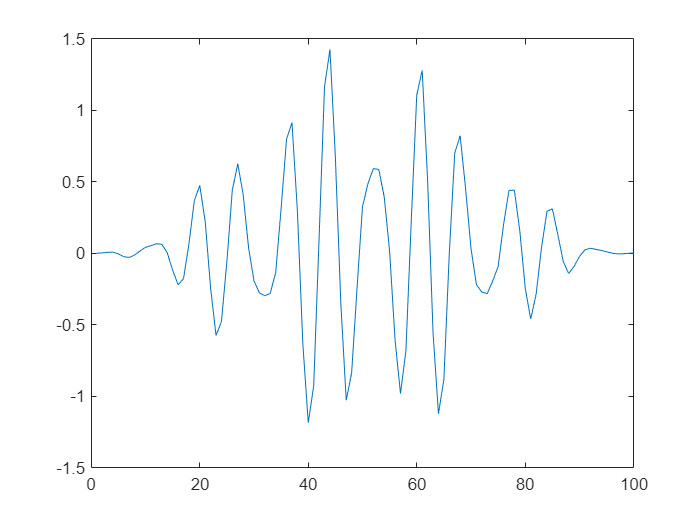

plot(x.*han)

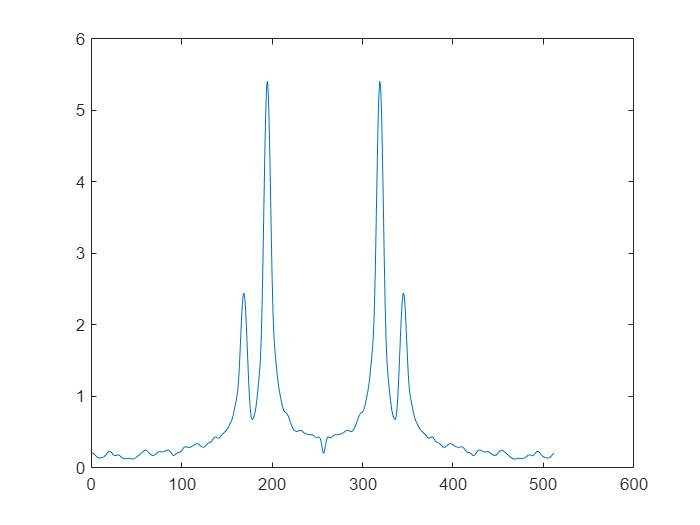

B = zeros([1, 512]);
han = hann(512)';
B(1:100) = x;
plot(abs(fftshift(fft(B.*han))))

function kwan = kwantiseer(a, b)
    a0 = (a - min(a)) / (max(a) - min(a));
    a1 = (power(2, b) - 1) * a0;
    a2 = round(a1);
    kwan = a2 * (max(a) - min(a)) / (power(2, b)) + min(a);
end